clear
addpath('E:\PhD\Adamantane_data\data')
addpath('E:\PhD\Anaconda2\ANACONDA_2\package\+smita\epicea')
addpath('E:\PhD\meetings_n_conf\2022\wk 14\Colormaps\Colormaps (5)\Colormaps')

S =data_list_adamantane;

## import the data if already converted to ANA

for f = 3%1: length(S)
    raw_data = IO.import_raw(S(f).dir_ada);
    mdata = IO.import_metadata(S(f).dir_ada);
    data            = macro.filter(raw_data, mdata); %define the multiplicity of events
    data_corrected = macro.correct(data, mdata);
    data_converted(f) = macro.convert(data_corrected, mdata);
    [data_stats(f)] =get_data_stats(data_converted(f));
    hv(f) = (S(f).photon);
end

Log: Detector image translation correction performed on det1
Log: Detector image rotation correction performed on det1
Log: Radial angle-dependent correction performed on det1
Log: Detector image translation correction performed on det2
Log: Detector image rotation correction performed on det2
Log: delta TOF correction performed on det2
Log: Lens abberation correction performed on det2


Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2


The Scaling factor is 0.51938


## PIPICO

% figure; hold on
% for i=3;%1:length(S)
%     subplot(1,3,i)
%     [Tet_tof2] = plot_pipico(data_converted(i), data_stats(i));
% %     [Tet_tof2] = plot_p_norm_p_norm(data_converted(i), data_stats(i),roi,m2q_1,m2q_2);
%     title([num2str(hv(i)), ' eV'])
% end

## PIPICO (ES FILTERED)

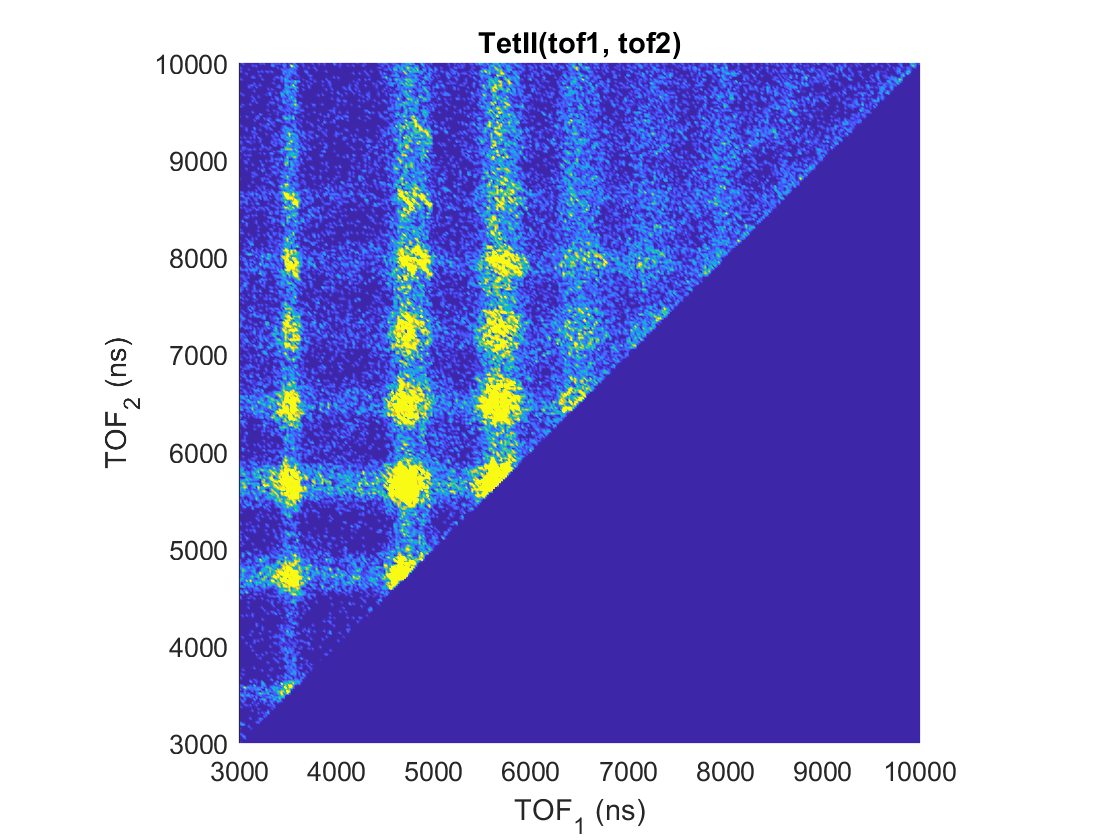

The Scaling factor is 0.50242


figure; %hold on
es_range = [230;280];
for i=3
% %     subplot(1,3,i)
    [data_stats_es_filt(i)] =get_data_stats_es_filt(data_converted(i),es_range);
    [Tet_tof2,Bincenters] = plot_pipico_es_filt(data_converted(i), data_stats_es_filt(i),es_range);
%     title([num2str(hv(i)), ' eV'])
end

% % sgtitle(sprintf('Region 0 : %.0f eV - %.1f eV', es_range(1),es_range(2)))
% [xvalues, c] = get_counts_in_roi(path, Tet_tof2, Bincenters );
% yvalues =xvalues;
% counts= sum(c,'all','omitnan');
% cdata = c.*100./counts;
% figure
% h = heatmap(xvalues,flip(yvalues),flip(cdata));
% cm_magma=magma(20);
% colormap(cm_magma)

path='E:\PhD\Adamantane_data\data\ascii_conv_data\Ada_PEPICO_hv350eV_ke260_0003_ascii\roi_final_filt\';

 [xvalues, c, d] = get_ker_in_roi(path,data_corrected)

Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 561
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 3325
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 4213
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 1071
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 1284
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 886
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 656
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 624
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 380
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 306
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 506
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 385
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 366
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 4494
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 1122
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 13983
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 2789
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 4240
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 654
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 934
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 918
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 1420
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 474
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 1299
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 1279
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 496
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 459
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 333
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 1478
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 778
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 215
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 181
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 350
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 926
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 929
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 569
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 390
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 8749
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 1750
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 4158
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 2890
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 789
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 1735
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 1587
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 633
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 1952
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 810
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 736
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 479
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 178
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 316
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 270
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 2476
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 1849
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 369
Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The Scaling factor is 0.51938
The number of events in ROI are 1383


xvalues = 1×18 cell array
    {'C1H3'}    {'C2H3'}    {'C2H4'}    {'C2H5'}    {'C3H3'}    {'C3H5'}    {'C4H3'}    {'C4H5'}    {'C4H6'}    {'C4H7'}    {'C5H3'}    {'C5H5'}    {'C5H7'}    {'C6H4'}    {'C6H5'}    {'C6H7'}    {'C7H7'}    {'C8H11'}


c =     6.3779       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.0170    4.0138       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN    2.7476       NaN    2.8179       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    4.7023    3.8454       NaN    2.6235    3.4944       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.7511    2.8338       NaN    2.6094    2.4374       NaN       NaN       NaN       NaN 

d =     2.4401       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    2.1092    1.9295       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN    1.6004       NaN    1.1618       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    2.0154    1.8375       NaN    1.3577    1.6070       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    1.7295    1.4024       NaN    1.3311    1.2090       NaN       NaN       NaN       NaN 

 yvalues =xvalues;
 %%

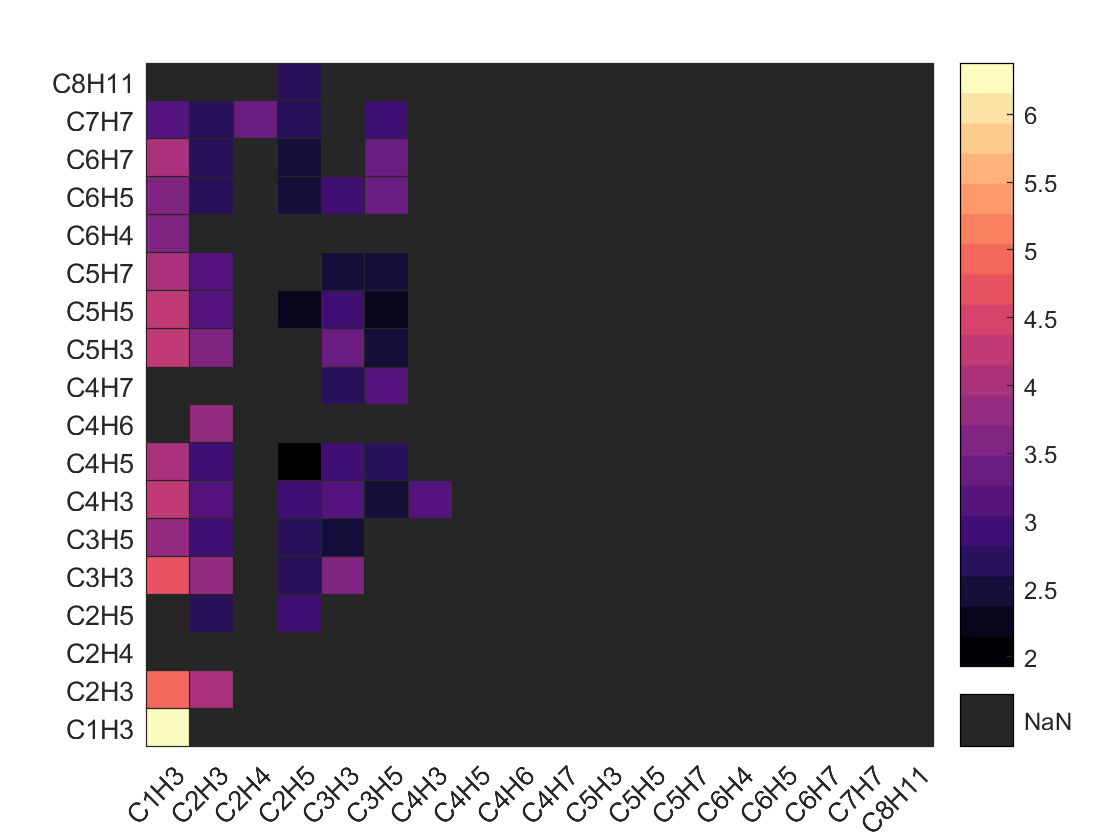


figure
h = heatmap(xvalues,flip(yvalues),flip(c));
cm_magma=magma(20);
colormap(cm_magma)
h.CellLabelFormat ='%0.2f ±  ';

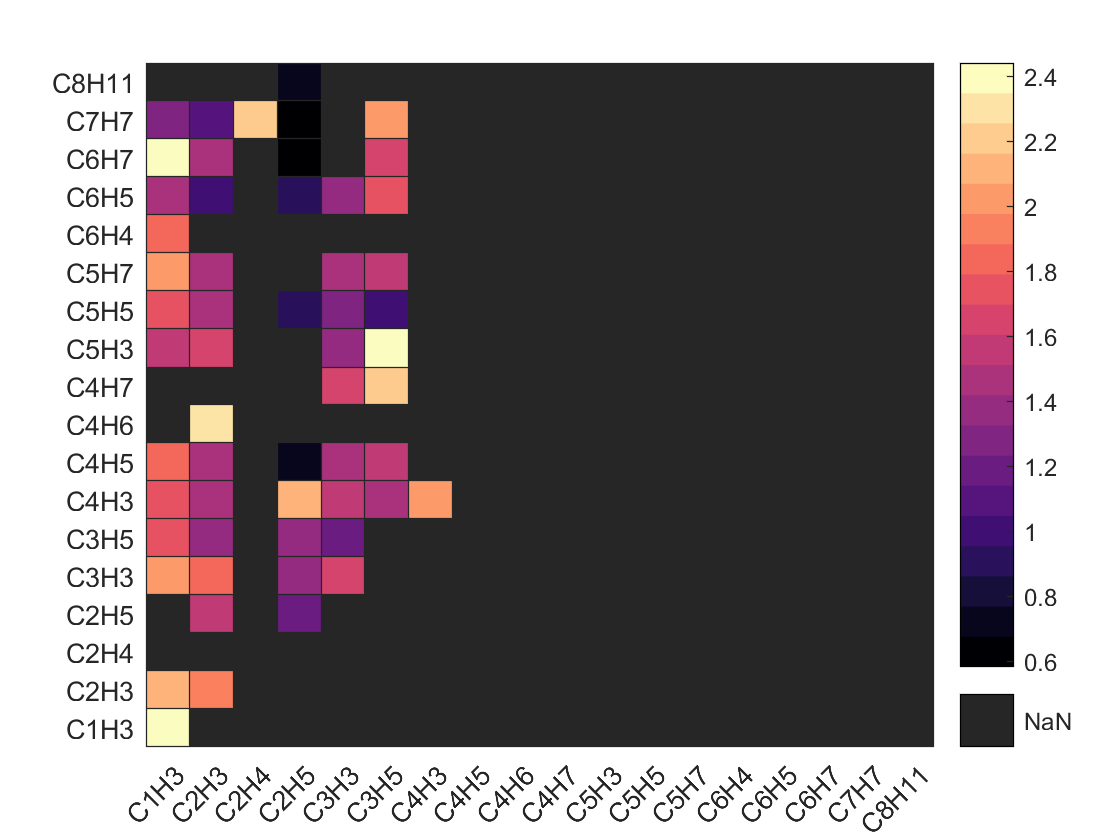


figure
h = heatmap(xvalues,flip(yvalues),flip(d));
cm_magma=magma(20);
colormap(cm_magma)

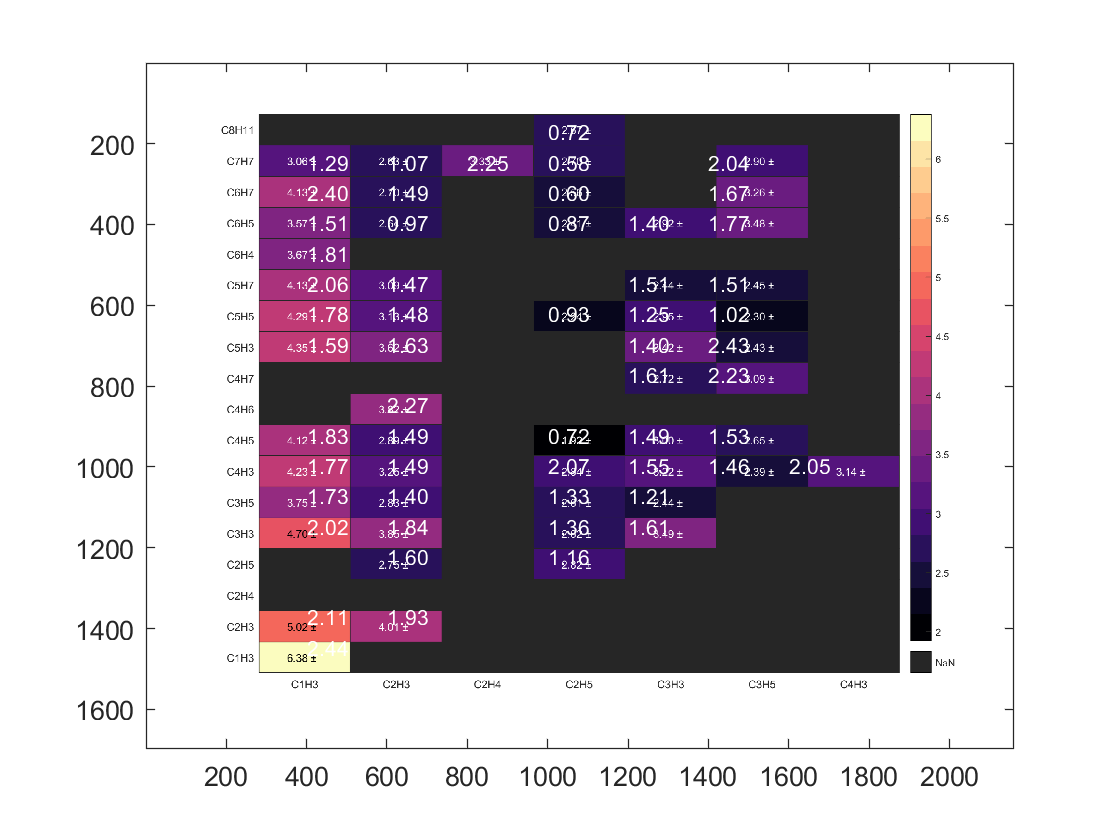


A = imread('E:\PhD\meetings_n_conf\2022\wk 16\ION_KER_ALL.png');
image(A)
e= flip(d);
    xx= 170;
for hh=1:length(d)
        yy= 430;
   for kk= 1:length(d)
       if ~isnan(e(hh,kk))
            text(yy,xx,sprintf('%0.2f',e(hh,kk)),'Color','w','FontSize',8)
       end
       yy = yy+230;
   end
   xx=xx+75;
end

% figure
% counts= sum([c{:,2}])./100;
% cdata =NaN(8,8);
% cdata(1:7,1)=[c{1:7,2}]./counts;
% cdata(2:8,2)= [c{8:14,2}]./counts;
% cdata(3:7,3)= [c{15:19,2}]./counts;
% cdata(4:6,4)= [c{20:22,2}]./counts;
% cdata(5,5)= [c{23,2}]./counts;
% labels =cell(1,8); for n=1:8; labels{1,n} = sprintf('C%i',n); end
% xvalues = labels; yvalues = labels;
% h = heatmap(xvalues,flip(yvalues),flip(cdata));
% colormap('hot')

%%

path='E:\PhD\Adamantane_data\data\ascii_conv_data\Ada_PEPICO_hv350eV_ke260_0003_ascii\roi_final_filt\';
[xvalues, c, d]  = get_ES_ion_pair_roi(path,data_converted(3), data_stats(3))

xvalues = 1×18 cell array
    {'C1H3'}    {'C2H3'}    {'C2H4'}    {'C2H5'}    {'C3H3'}    {'C3H5'}    {'C4H3'}    {'C4H5'}    {'C4H6'}    {'C4H7'}    {'C5H3'}    {'C5H5'}    {'C5H7'}    {'C6H4'}    {'C6H5'}    {'C6H7'}    {'C7H7'}    {'C8H11'}


c =   248.4782       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  248.4946  247.7410       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN  251.1295       NaN  255.3488       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  249.3488  248.3635       NaN  251.9553  248.1337       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  250.8434  251.2895       NaN  259.4229  250.6582       NaN       NaN       NaN       NaN 

d =     4.9733       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.1869    4.3031       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN    3.9000       NaN    7.0334       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.1829    4.6476       NaN    8.1274    4.8363       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.2097    4.5491       NaN    6.8752    4.6188       NaN       NaN       NaN       NaN 

yvalues =xvalues;
 %%

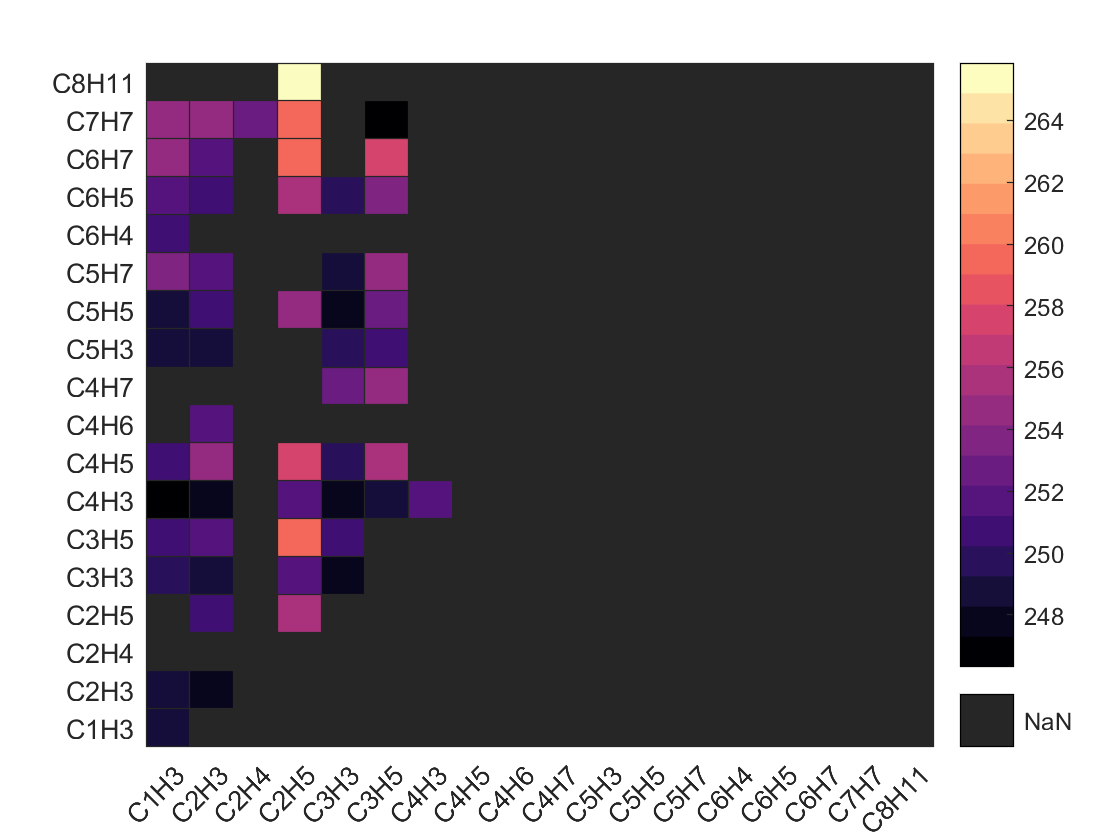


figure
h = heatmap(xvalues,flip(yvalues),flip(c));
cm_magma=magma(20);
colormap(cm_magma)
h.CellLabelFormat ='%0.2f ±  ';

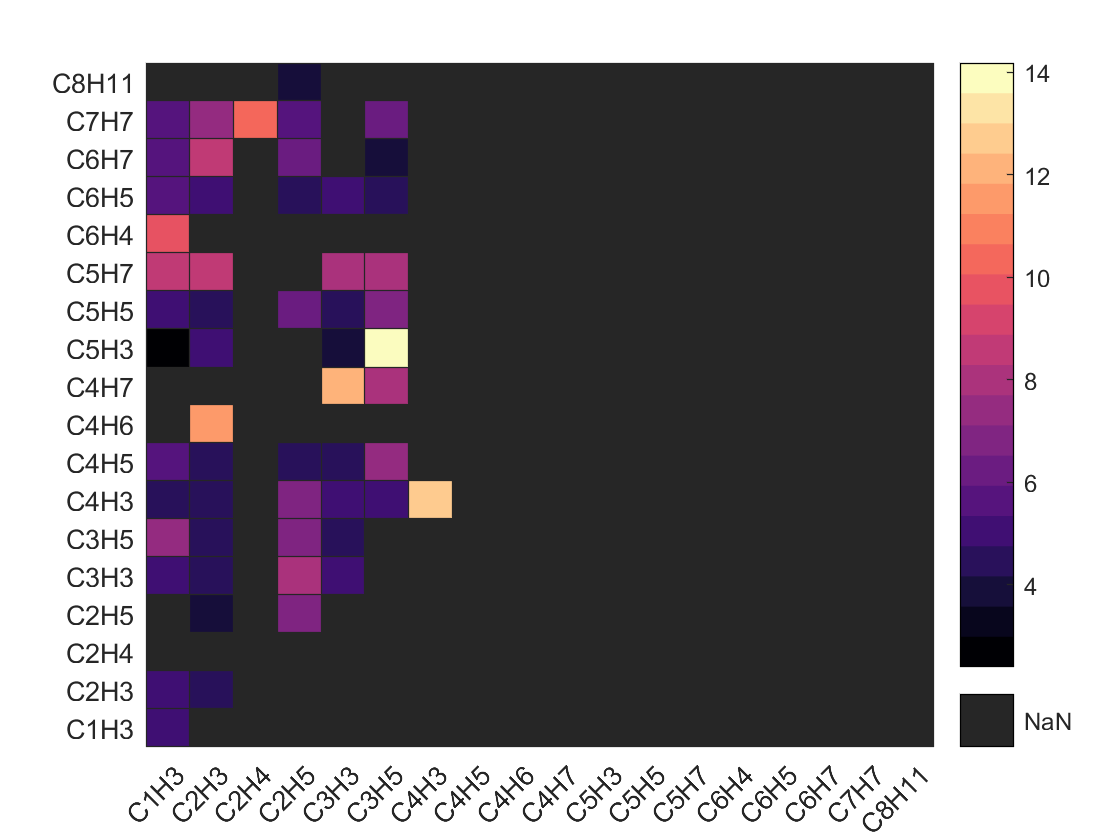


figure
h = heatmap(xvalues,flip(yvalues),flip(d));
cm_magma=magma(20);
colormap(cm_magma)

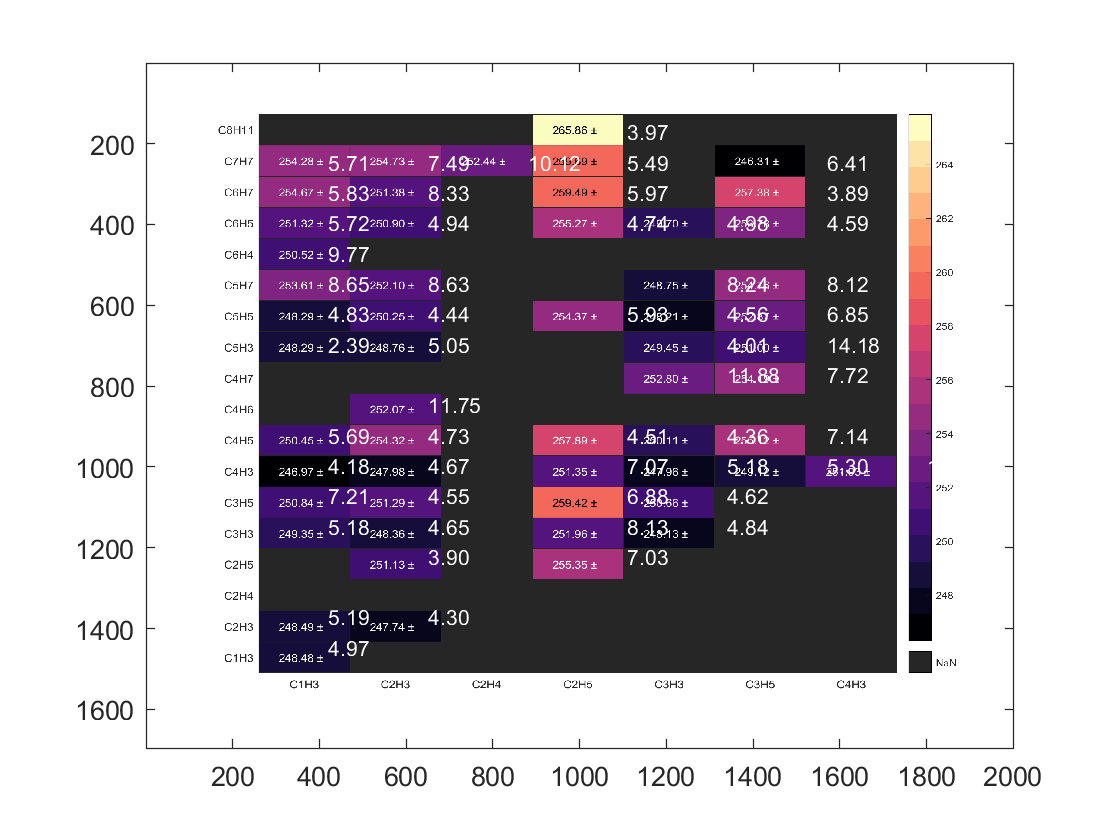


A = imread('E:\PhD\meetings_n_conf\2022\wk 16\ION_AES_ALL.png');
figure
image(A)
e= flip(d);
    xx= 170;
for hh=1:length(d)
        yy= 418;
   for kk= 1:length(d)
       if ~isnan(e(hh,kk))
            text(yy,xx,sprintf('%0.2f',e(hh,kk)),'Color','w','FontSize',7)
       end
       yy = yy+210;
   end
   xx=xx+75;
end

## Load ROI

c1 = 2;  h1 =5; c2= 8; h2=11;
m2q_1 = 12*c1+h1; m2q_2 = 12*c2+h2;
filename= sprintf('c%ih%i_c%ih%i',c1,h1,c2,h2);
% filename= sprintf('c%i_c%i',c1,c2);

path='E:\PhD\Adamantane_data\data\ascii_conv_data\Ada_PEPICO_hv350eV_ke260_0003_ascii\roi_final\';%_carbons_new\new_folder';
load([path,filename,'.mat'],'roi')
mdata = IO.import_metadata(S(3).dir_ada);
mdata.plot.det2.TOF_hit1_hit2.cond.C2H5.value=m2q_1;
mdata.plot.det2.TOF_hit1_hit2.cond.C8H11.value=m2q_2;
% macro.plot(data_converted(3),mdata);
% drawellipse('Color','r', 'Center',roi.Center,'SemiAxes',roi.SemiAxes,'FaceAlpha',0,'InteractionsAllowed','none','RotationAngle',roi.RotationAngle);


## ION Kinetic energy Two ion events

% [e_filter_roi, ~] = filter.epicea.find_events_in_roi(data_converted(3),roi,m2q_1,m2q_2);
[e_filter_roi, ~] = find_events_in_roi(data_converted(3),roi);

figure; hold on
plot_signal=struct();
plot_signal.hit.data_pointer = 'data_converted.h.det2.KER';
% plot_signal.hit.data_pointer = 'data_converted.h.det2.R';
plot_signal.hit.label = 'Ion kinetic energy (eV)';%dp_{norm}
% plot_signal.Binsize =2; plot_signal.Range =[0, 30]; 
plot_signal.Binsize =0.5; plot_signal.Range =[0, 20]; 
% plot_signal.Binsize =0.1; plot_signal.Range =[0, pi]; 

plot_signal.event.data_pointer = 'data_converted.e.det2.KER_sum';
% plot_signal.event.data_pointer = 'data_converted.e.det2.angle_p_corr_C2';
plot_signal.event.label = 'Ion pair KER (eV)';%p_{1z} + p_{2z}
[Tet_ev_mean,Tet_ev_std] =plot.epicea.plot_ion_c2(data_converted(3), data_stats(3),e_filter_roi,plot_signal,m2q_1,m2q_2);
% legend(filename)

% figure; hold on
% plot_signal=struct();
% plot_signal.hit.data_pointer = 'data_converted.h.det2.dp_norm';
% plot_signal.hit.label = 'Ion |p|';%dp_{norm}
% plot_signal.Binsize =10; plot_signal.Range =[0, 300]; 
% 
% plot_signal.event.data_pointer = 'data_converted.e.det2.dp_sum_norm';
% plot_signal.event.label = 'Ion pair |p_{1} + p_{2}|';%p_{1z} + p_{2z}
% [e_filter_et,e_filter_rt] =plot.epicea.plot_ion_c2(data_converted(3), data_stats(3),e_filter_roi,plot_signal,m2q_1,m2q_2);
% legend(filename)

## Ion pair specific Electron Spectra

% macro.plot(data_converted, mdata)
figure
tof_1 =[roi.Center(1)-500 ; roi.Center(1)+500];
tof_2 =[roi.Center(2)-500 ; roi.Center(2)+500];
[TES2IIpair_x, Xcenters] = plot_ES_ion_pair_c2(data_converted(3), data_stats(3),roi,tof_1,tof_2);
%% give name
e_KE_mean = sum(TES2IIpair_x.*Xcenters)/sum(TES2IIpair_x)

